# TARATURA DEL GIUNTO 1

clear all
close all
clc

dopo aver caricato il modello del giuntoi, tramite la funzione damp si identificano le frequenze per trovare le frequenze di risonnza del modello

load ..\file_mat_init\ide_giunto1.mat


G1 = modello_continuo_g1_3rd;
dataG1=damp(G1)

dataG1 =    77.2900
  674.4549
  674.4549


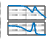

figure
bode(G1)
grid on
title('Diagramma bode identificazione Giunto 1')

# TARATURA LOOP INTERNO CONTROLLORE PI

# e_vel -> PI -> FILTRO NOTCH -> FILTRO PASSA BASSO -> u

## **FILTRO NOTCH**

**avendo il sistema un picco di risonanza all wn = 674 rad/s si è deciso di inserire un filtro notch per abbassare il picco di risonanza.**


$$\mathrm{Fn}\left(s\right)=\frac{s^{2\;} +2\cdot x{\mathrm{ci}}_{\mathrm{z1}} \cdot Wn_{\mathrm{notch1}} \cdot s+Wn_{\mathrm{notch1}}^2 }{s^{2\;} +2\cdot x{\mathrm{ci}}_{\mathrm{z1}} \cdot Wn_{\mathrm{notch1}} \cdot s+Wn_{\mathrm{notch1}}^2 }$$


Di seguito viene progettato il filtro notch elimina banda con una frequenza vicina a 674 rad/s per rendere il diagramma di bode del filtro in serie al sistema più smooth

Poi per tentativi, sono stati decisi i valori "ottimali" di xci_z e xci_p che indicano la selettività del filtro notch

Wn_notch1 = 680;
xci_z1=0.15;%0.15; %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p1=0.7;%0.7;
s=tf('s');
Fn1_vel=(s^2+2*xci_z1*Wn_notch1*s+Wn_notch1^2)/(s^2+2*xci_p1*Wn_notch1*s+Wn_notch1^2);

Verifica del filtro mediante l'utilizzo dei diagrammi di bode

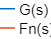

figure
bode(G1)
hold on
bode(Fn1_vel)
grid on
bode(Fn1_vel*G1)
hold off
set(findall(gcf,'type','line'),'linewidth',1.5)
legend('G(s)','Fn(s)','G(s)*Fn(s)','Location','best')
title('Giunto 1 inserimento filtro notch ')

## FILTRO PASSA BASSO

Prima di procedere con la taratura del controllore PI per il loop interno si inserisce un filtro passa basso per attenuare le alte frequenze dell'azione di controllo che possono essere dovute dall'influenza del rumore del sul sensore


$$F\left(s\right)=\frac{1}{\textrm{Tf}\cdot \;s+1}$$


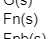

Tf1_vel = (1/2000);
F1_vel = tf(1,[Tf1_vel 1]);


figure
bode(G1)
hold on 
bode(Fn1_vel)
bode(F1_vel)
bode(Fn1_vel*F1_vel*G1)
legend('G(s)','Fn(s)','Fpb(s)','Fn(s)*Fpb*G(s)','Location','best')
grid on
hold off
set(findall(gcf,'type','line'),'linewidth',1.5)
title('Giunto 1 + filtro notch inserimento filtro passa basso ')

## CONTROLLORE PI

si calcola funzione a destra del controllore che è data dalla serie dei filtri e del sistema prima di iniziare la tarature.

Si è deciso di utilizzare una taratura manuale rispetto alla taratura automatica con i vincoli per avere una miglior possibilità di scelta sulla w di taglio essendo che con il tuning automatico predilige il valore di massima sensitività che solitamente viene scelto tra [1.4 2]  

G1nf= Fn1_vel*F1_vel*G1;

la wc desiderata è stata calcola in maniera tale che il picco nella zona di risonanza sia attenuato di almeno 6dB

wc_des=160; % omega di taglio desiderata in rad/s in maniera da garantire l'attenuazione richiesta
wi_vel1 = wc_des/30; % omega dellazione integrale che viene posiizonata all'incirca una decade prima della omega di taglio del sistema
Ti_vel1 = 1/wi_vel1; % calcolo della costante di tempo integrale
s = tf('s');

Kp1_vel=(1/abs(freqresp(G1nf,wc_des))); % calcolo del valore di Kp neccessario al controllore per garantire la wc desiderata
Ki1_vel = Kp1_vel/Ti_vel1; %riaggiorno il Ki dell'azione integrale

Kaw1 = Ki1_vel/Kp1_vel; % calcolo Kaw per il fenomeno di anti-windup
C1pi=tf([Kp1_vel Ki1_vel],[1 0]);%genero il ocntrollore nella forma Kp*(1 + ki/s)


si utilizza il grafico di bode per verificare l'attenuazione richiesta e tramite la funzione margin verifico l'omega di taglio del sistema e del valore di margine di fase del loop e di seguito si esegue uno step del loop per essere sicuri dei dati ottenuti

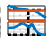

L1 = C1pi*G1nf;
figure
margin(L1)
hold on
bode(tf(0.50115))
set(findall(gcf,'type','line'),'linewidth',1.5)
grid on

di seguito si genera un vettore di frequenze per il calcolo della massima sensitività che deve essere <= 1.4 per avere un controllore robusto

w_vector=logspace(-4,10)'; %vettore per lo 
C_fr = freqresp(L1,w_vector);
S_fr = 1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.0794

## Verifica con STEP

per sicurezza si verifica che la risposta allo scalino dell'anello interno sia come ci aspettiamodalla taratura effettuata.

la funzione dell'anello interno è calcolata come segue:


$$\textrm{L1ret}=\frac{\textrm{PI}\cdot \textrm{Fn}\cdot \textrm{Fpb}\cdot \textrm{G1}}{1+\textrm{PI}\cdot \textrm{Fn}\cdot \textrm{Fpb}\cdot \textrm{G1}}=\frac{\textrm{L1}}{1+\textrm{L1}\;}\Rightarrow \;\textrm{feedback}\left(\textrm{L1},1\right)$$


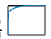

L1ret = feedback(L1,1);
figure
step(L1ret)

# TARATURA LOOP ESTERNO CONTROLLORE P

# e_pos -> P -> FILTRO PASSA BASSO -> u_pos

per passare dalla velocità alla posizone introduciamo un integrale mediante 1/s e grafichiamo il sistema per semlicità per la  fase di taratura

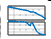

G1e = L1ret*1/s;
bode(G1e)
grid on

## FILTRO PASSA BASSO

Prima di procedere con la taratura del controllore P per il loop esterno si inserisce un filtro passa basso per attenuare le alte frequenze dell'azione di controllo che possono essere dovute dall'influenza del rumore del sul sensore


$$F\left(s\right)=\frac{1}{\textrm{Tf}\cdot \;s+1}$$


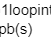

Tf1_pos = (1/2000);
F1_pos = tf(1,[Tf1_pos 1]);

figure
bode(G1e)
hold on 
bode(F1_pos)
bode(F1_pos*G1e)
legend('G1loopint(s)','Fpb(s)','Fpb(s)*G1loopint(s)','Location','best')
grid on
hold off
set(findall(gcf,'type','line'),'linewidth',1.5)
title('Giunto 1 l1int/s + filtro passa basso ')

## **CONTROLLORE P -> LOOP ESTERNO **

wc_esterno = 105;
Kp1_pos=1/abs(freqresp(F1_pos*G1e,wc_esterno));

Cp1=Kp1_pos;

di seguito si genera un vettore di frequenze per il calcolo della massima sensitività che deve essere <= 1.4 per avere un controllore robusto

C_fr=freqresp(Cp1*F1_pos*G1e,w_vector);
S_fr=1./(1+(C_fr)); % S = 1/(1+L) sensitivity function
max(abs(S_fr))

ans = 1.4125

tramite la funzione margin verifico l'omega di taglio del sistema del loop esterno e del valore di  del margine di fase del loop e di seguito si esegue uno step del loop per essere sicuri dei dati ottenuti

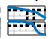

figure
margin(Cp1*F1_pos*G1e)
set(findall(gcf,'type','line'),'linewidth',1.5)
grid on

## Verifica con STEP

per sicurezza si verifica che la risposta allo scalino dell'anello interno sia come ci aspettiamodalla taratura effettuata.

la funzione dell'anello interno è calcolata come segue:

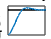

step(feedback(Cp1*F1_pos*G1e,1))

# Sezione di salvataggio dei parametri trovati nella fase di taratura

save("..\file_mat_init\ctrl1.mat","Kp1_pos","Kp1_vel","Ki1_vel","Kaw1","Tf1_vel","Tf1_pos","Wn_notch1","xci_p1","xci_z1")